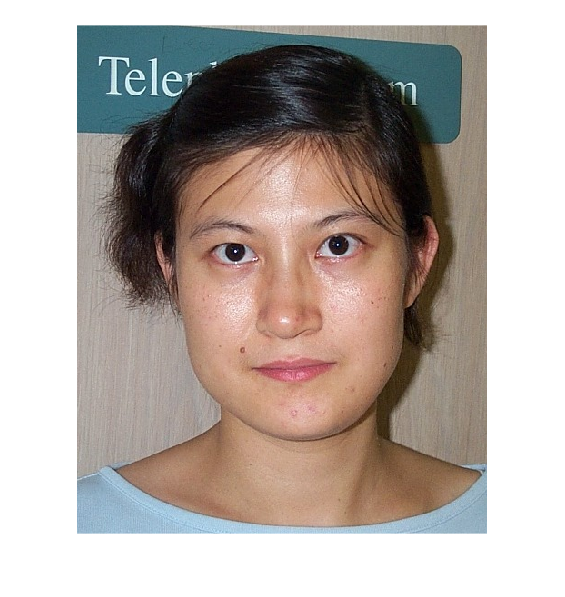

clear
picNumber = 3;
original = imread("..\db\DB0\db0_" + picNumber + ".jpg");
grayscale = im2gray(original);
eye_map = imread("eyeMask" + picNumber + ".png");
mouth_map = imread("mouthMask" + picNumber + ".png");

imshow(original)

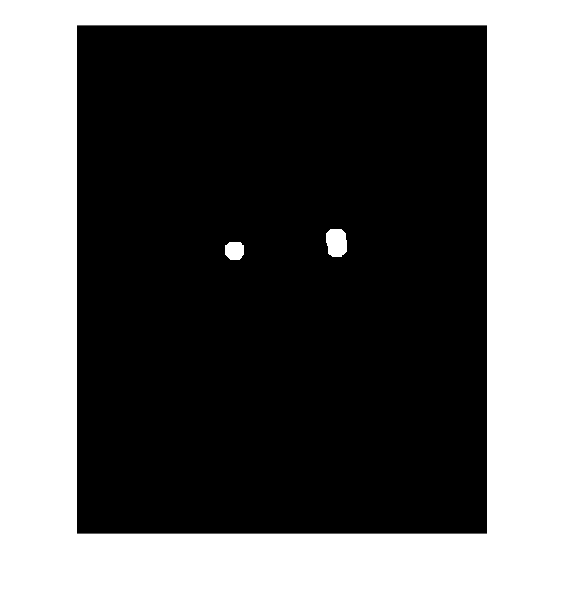


threshold_eye = 175;
eye_mask = eye_map > threshold_eye;
eyeSE = strel('disk',10);
eye_mask = imopen(eye_mask,eyeSE);
imshow(eye_mask)

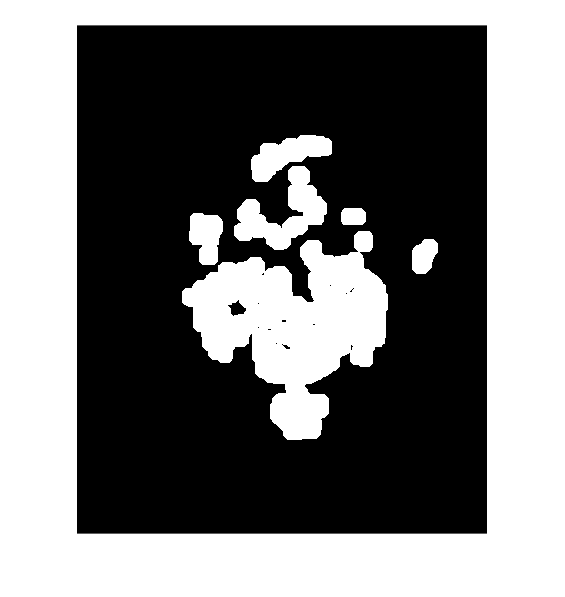


threshold_mouth = 3;
mouth_mask = mouth_map > threshold_mouth;
mouthSE = strel('disk',10);
mouth_mask = imopen(mouth_mask,mouthSE);
imshow(mouth_mask)

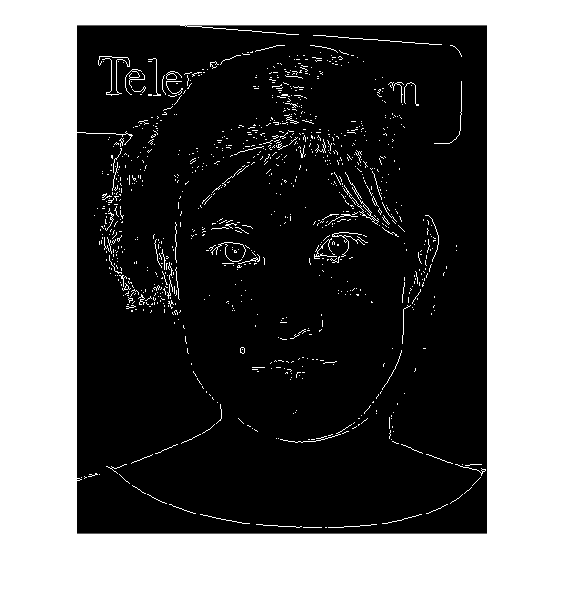



edges = edge(grayscale);
imshow(edges)

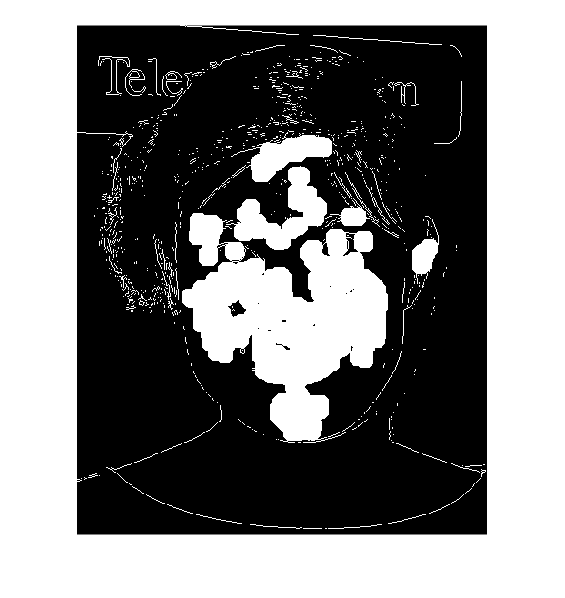


faceMask = eye_mask | mouth_mask | edges;

imshow(faceMask)


% imshow(original)
% imshow(eyeMask)
% imshow(mouthMask)